# **wavelet-RnB Live, version 02**

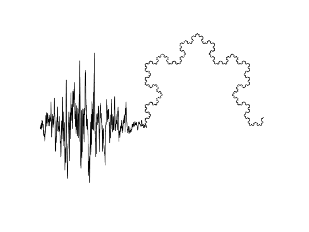

## *wRnB demo with 4 intracranial regions *

#### *(J.M. Lina, M-C. Foti, 2024)*

#### The wRnB is a wavelet-based processing aiming at disantangling the rhythmic and arrhythmic components of electrophysiological signals.

#### The main reference: J. Dubé et al., *Rhythms and Background (RnB): the spectroscopy of sleep recordings*, 2024 

 
clc; clear; close all;
restoredefaultpath;
% librairy RnB
addpath(genpath('./RnB_v01'), 'data')
make_introd();


    This demo applies the wavelet-RnB algorithm to produce the
    spectrum of scaling exponents and the 'rhythmic spectral
    annalysis from a collection of epochs.
    The multiresolution analysis is obtained from an orthonormal 
    discrete wavelet basis in the fractional spline family (T.Blu
    and M.Unser, 1993)
    The 'sleep data' are samples from the MNI-open iEEG atlas
    (N. Ellenrieder et al., 2020)


#### You can choose a region: 

 close all
region = 2 ;

   dbs = dir('data/R*');
   load([dbs(region).folder filesep dbs(region).name])
   make_status(region,data_epochs,fs);


    You selected Supp. Motor Cortex:
	 . 300 epochs
	 . 4096 samples (20.48 seconds @ 200.00 Hz)
	 . The wRnB will take max. 1.7 minutes, press RnB ...
    and wait ...

 
tic
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%                         
[sR, pW] = wRnB_extract_Rhythmic_signals(data_epochs,'alpha', 4,'J', 8,'verbose',0);%
pR = RnB_compute_spectre_brut(sR,fs);                                               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
toc

Elapsed time is 43.627571 seconds.


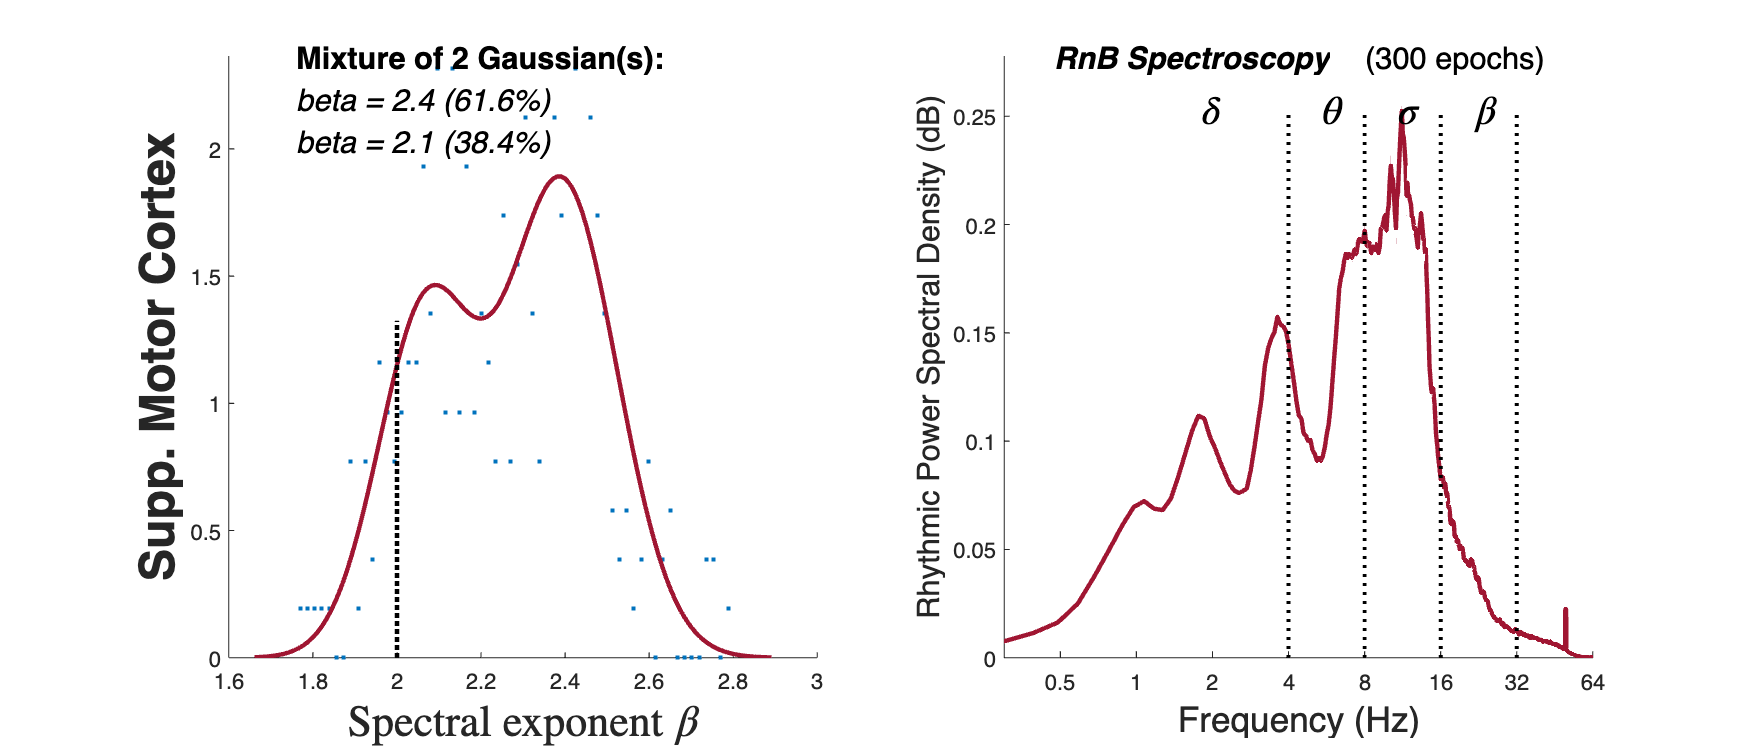


    The left figure displays the distribution of the scaling
    exponent across the epochs. The curve is an optimal fit
    (in terms of an optimal Akaike Index Criteria) with a mixture
    of Gaussians. The right figure shows the 'RnB spectroscopy'
    of the Supp. Motor Cortex during NREM sleep.


% Display 
make_figure(pR,pW,sR,region);

fprintf('\nBye.\n')


Bye.
